# MATLAB(R)/Simulink(R) & Raspberry Pi で学ぶ組込みビジョン！

## EmbVisionチュートリアル(CQ版)HTMLドキュメント発行ライブスクリプト

本ライブスクリプトPUBLISHALLCQは、EmbVisionチュートリアル(CQ版)のHTMLドキュメントを発行します。

本資料は、新潟大学工学部電気電子工学科専門科目「電気電子創造設計」(2014年度開講）の課題として作成したものを，CQ出版社Interface 2022年9月号記事用に再編集したものです。

#### 作成者

- 新潟大学　村松　正吾，高橋　勇希

Copyright (c), All rights reserved, 2014-2022, Shogo MURAMATSU and Yuki TAKAHASHI

## 準備

proj = 'cq';
type = 'html';
targetdir = [ '+cq/' type '/' ];

if ~exist(targetdir,'dir')
    mkdir(targetdir)
end

## Index

publish([proj '.index'],type);

## Part 1

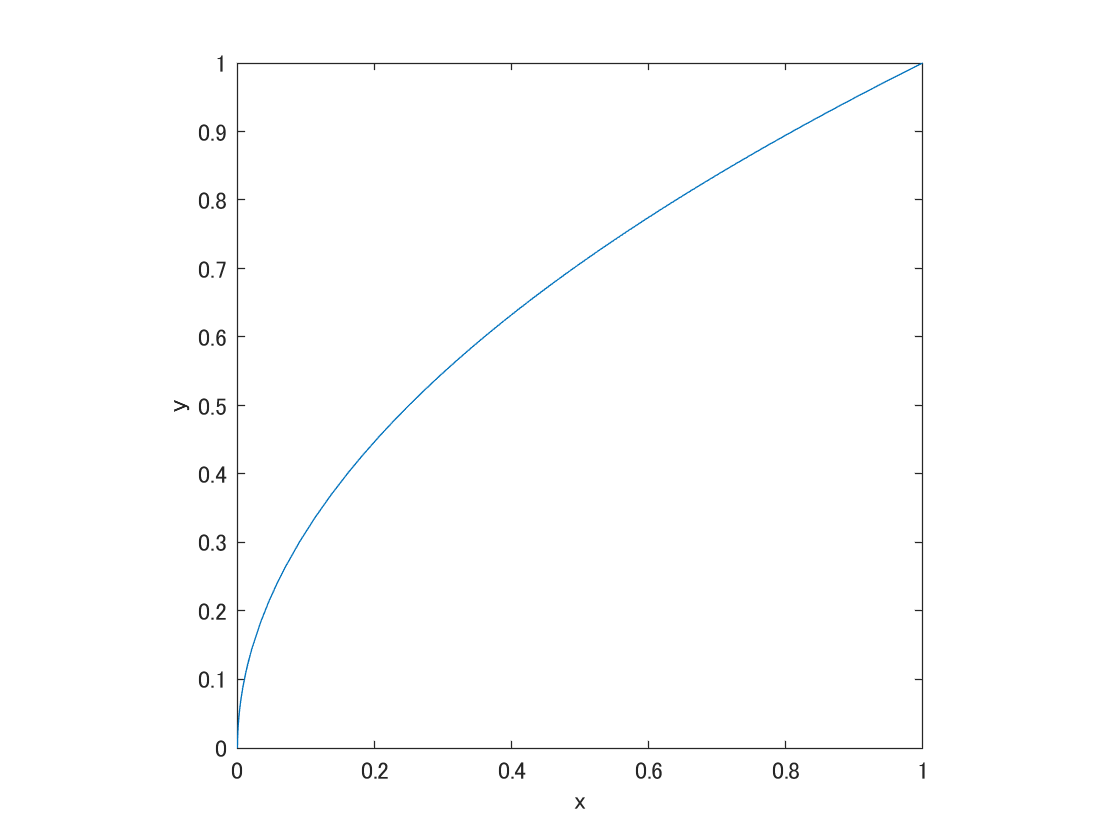

close all

% Exercise 1-1
RGB = imread('peppers.png');
I = im2double(rgb2gray(RGB));
J = sqrt(I);
imwrite(J,[targetdir 'brightpeppers.png'])
fplot(@sqrt,[0 1])
xlabel('x')
ylabel('y')
axis square
print('-dpng','-r72',[targetdir 'fplotsqrt.png'])


% Exercise 1-2
HSV = rgb2hsv(RGB);
HSV(:,:,2) = 2*HSV(:,:,2);
J = hsv2rgb(HSV);
imwrite(J,[targetdir 'highsatpeppers.png'])

% Publish
publish([proj '.part1'],type);

## Part 2

close all

% Exercise 2-1
X = imread('cameraman.tif');
X = im2double(X);

Hh = [ 1 0 -1; 1 0 -1; 1 0 -1 ];
Yh = conv2(Hh,X);
Yh = Yh(2:end-1,2:end-1);
imwrite(Yh+0.5,[targetdir 'cameramangradx.png'])

freqz2(Hh)
print('-dpng','-r72',[targetdir 'freqz2gradx.png'])

% Exercise 2-2
Hv = [ 1 1 1; 0 0 0; -1 -1 -1 ];
Yv = conv2(Hv,X);
Yv = Yv(2:end-1,2:end-1);

dXmag = sqrt(Yv.^2+Yh.^2);
dXang = atan2(Yv,Yh);

imwrite(dXmag,[targetdir 'cameramangradmag.png'])
imwrite(dXang/(2*pi)+0.5,[targetdir 'cameramangradang.png'])

% Publish
publish([proj '.part2'],type);

## Part 3

close all

addpath('workcq/part3')
publish([proj '.part3'],type);
rmpath('workcq/part3')

## Part 4

...

% Exercise 4-1
...
% Exercise 4-2
...

% Publish
publish([proj '.part4'],type);

## Part 5

close all

addpath('workcq/part5')

%
copyfile('workcq/part5/shuttleclone.png',[targetdir 'shuttleclone.png']);
copyfile('workcq/part5/shuttlegrad.png',[targetdir 'shuttlegrad.png']);
copyfile('workcq/part5/shuttleave.png',[targetdir 'shuttleave.png']);
copyfile('workcq/part5/shuttlesobel.png',[targetdir 'shuttlesobel.png']);
copyfile('workcq/part5/shuttlediff.png',[targetdir 'shuttlediff.png']);

% Exercise 5-1
vrObj = VideoReader('shuttle.avi');
frameRate = get(vrObj,'FrameRate');
vwObj = VideoWriter('shuttlesobel.avi');
set(vwObj,'FrameRate',frameRate);
rgsObj = Rgb2GraySystem();
hrsObj = Hsv2RgbSystem();
gfsObj = GradFiltSystem('Kernel',[1 2 1; 0 0 0 ; -1 -2 -1]);
open(vwObj)
while (hasFrame(vrObj))
    frame     = readFrame(vrObj);         % Read frame
    graysc    = step(rgsObj,frame);       % To grayscale
    [mag,ang] = step(gfsObj,graysc);      % Gradient filtering
    ang       = (ang+pi)/(2*pi);          % Normalize angle
    mag       = min(mag,1);               % Saturate magnitude
    [r,g,b]   = step(hrsObj,ang,mag,mag); % To pseudo color
    frame     = cat(3,r,g,b);             % Concatinate RGB array
    writeVideo(vwObj,frame);              % Write frame
end
close(vwObj)

% Exercise 5-2
% vrObj = VideoReader('shuttle.avi');
% frameRate = get(vrObj,'FrameRate');
% vwObj = VideoWriter('shuttlediff.avi');
% set(vwObj,'FrameRate',frameRate);
% fdfObj = FrameDiffSystem();
% open(vwObj)
% while (hasFrame(vrObj))
%     frame = readFrame(vrObj);   % Read frame
%     frame = im2double(frame);   % To float type
%     frame = step(fdfObj,frame); % Frame difference
%     frame = frame/2+0.5;        % Adjust for display
%     writeVideo(vwObj,frame);    % Write frame
% end
% close(vwObj)

%
publish([proj '.part5'],type);
rmpath('workcq/part5')

## Part 6

close all

addpath('workcq/part6')

%
copyfile('workcq/part6/videoio_slx_00.png', [targetdir 'videoio_slx_00.png']);
copyfile('workcq/part6/videoio_slx_01.png', [targetdir 'videoio_slx_01.png']);
copyfile('workcq/part6/videoio_slx_02.png', [targetdir 'videoio_slx_02.png']);
copyfile('workcq/part6/videoio_slx_03.png', [targetdir 'videoio_slx_03.png']);
copyfile('workcq/part6/videoio_slx_04.png', [targetdir 'videoio_slx_04.png']);
copyfile('workcq/part6/videorgb2gray_slx_00.png', [targetdir 'videorgb2gray_slx_00.png']);
copyfile('workcq/part6/videorgb2gray_slx_01.png', [targetdir 'videorgb2gray_slx_01.png']);
copyfile('workcq/part6/videorgb2gray_slx_02.png', [targetdir 'videorgb2gray_slx_02.png']);
copyfile('workcq/part6/videorgb2gray_slx_03.png', [targetdir 'videorgb2gray_slx_03.png']);
copyfile('workcq/part6/videogradfilt_slx_00.png', [targetdir 'videogradfilt_slx_00.png']);
copyfile('workcq/part6/file_button.png', [targetdir 'file_button.png']);
copyfile('workcq/part6/library_button.png', [targetdir 'library_button.png']);
copyfile('workcq/part6/play_button.png', [targetdir 'play_button.png']);
copyfile('workcq/part6/library_browser.png', [targetdir 'library_browser.png']);
copyfile('workcq/part6/cvs_library.png', [targetdir 'cvs_library.png']);
copyfile('workcq/part6/cvs_sources.png', [targetdir 'cvs_sources.png']);
copyfile('workcq/part6/cvs_sources_blocks.png',[targetdir 'cvs_sources_blocks.png']);
copyfile('workcq/part6/cvs_sinks.png', [targetdir 'cvs_sinks.png']);
copyfile('workcq/part6/cvs_sinks_blocks.png', [targetdir 'cvs_sinks_blocks.png']);
copyfile('workcq/part6/frommultimediafile_blockparameter.png', [targetdir 'frommultimediafile_blockparameter.png']);
copyfile('workcq/part6/tomultimediafile_blockparameter.png', [targetdir 'tomultimediafile_blockparameter.png']);
copyfile('workcq/part6/matlabsystem_blockparameter.png', [targetdir 'matlabsystem_blockparameter.png']);
copyfile('workcq/part6/imaq_blocks.png', [targetdir 'imaq_blocks.png']);
copyfile('workcq/part6/udf_blocks.png', [targetdir 'udf_blocks.png']);
copyfile('workcq/part6/vipmengradfilt_avi.png', [targetdir 'vipmengradfilt_avi.png']);
copyfile('workcq/part6/vipmengradfilt_sobel_avi.png', [targetdir 'vipmengradfilt_sobel_avi.png']);

%
publish([proj '.part6'],type);
rmpath('workcq/part6')

## Part 7

close all

addpath('workcq/part7')

copyfile('workcq/part7/raspberrypi_blocks.png', [targetdir 'raspberrypi_blocks.png']);
copyfile('workcq/part7/gradfilt_kernel.png', [targetdir 'gradfilt_kernel.png']);
copyfile('workcq/part7/raspi_microsd.png', [targetdir 'raspi_microsd.png']);
copyfile('workcq/part7/raspi_cableconnection.png', [targetdir 'raspi_cableconnection.png']);
copyfile('workcq/part7/raspi_hdmi.png', [targetdir 'raspi_hdmi.png']);
copyfile('workcq/part7/raspi_videogradfilt.png', [targetdir 'raspi_videogradfilt.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_00.png', [targetdir 'videogradfiltraspi_slx_00.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_01.png', [targetdir 'videogradfiltraspi_slx_01.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_02.png', [targetdir 'videogradfiltraspi_slx_02.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_03.png', [targetdir 'videogradfiltraspi_slx_03.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_04.png', [targetdir 'videogradfiltraspi_slx_04.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_05.png', [targetdir 'videogradfiltraspi_slx_05.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_06.png', [targetdir 'videogradfiltraspi_slx_06.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_07.png', [targetdir 'videogradfiltraspi_slx_07.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_08.png', [targetdir 'videogradfiltraspi_slx_08.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_09.png', [targetdir 'videogradfiltraspi_slx_09.png']);
copyfile('workcq/part7/videogradfiltraspi_slx_10.png', [targetdir 'videogradfiltraspi_slx_10.png']);
copyfile('workcq/part7/videogradfiltraspi_external.png', [targetdir 'videogradfiltraspi_external.png']);
copyfile('workcq/part7/videogradfiltraspi_ipaddress.png', [targetdir 'videogradfiltraspi_ipaddress.png']);

%
publish([proj '.part7'],type);
rmpath('workcq/part7')

## ZIP作成

close all

cdir = pwd;
cd(['+' proj])
if exist(['html/embvision_' proj '.zip'],'file')==2
    delete(['html/embvision_' proj '.zip'])
    disp(['Old embvision_' proj '.zip was deleted.'])
end

Old embvision_cq.zip was deleted.


zip(['embvision_' proj], 'html')
movefile(['embvision_' proj '.zip'], 'html')
cd(cdir)

## HTMLドキュメントのオープン

showdemo([proj '.index'])

## 本ライブスクリプトのPDF化

export("publishallcq.mlx")

ans = 'C:\Users\shogo\Workspace\GitHub\EmbVision\publishallcq.pdf'